clear; clc;
dataQtd = 100;
centersQtd = 4;
epochMax = 100;

#### 1 - Define o conjuto de dados 

data1 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(5,dataQtd,1)+15]-randi(3,dataQtd,1);
data2 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)+15]-randi(5,dataQtd,1);
data3 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(3,dataQtd,1);
data4 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(4,dataQtd,1);

data = [data1; data2; data3; data4];
realClasses = [linspace(1,1,length(data1)) linspace(2,2,length(data2)) linspace(3,3,length(data3)) linspace(4,4,length(data4))];

#### 2 - Inicializa os centros dos grupos

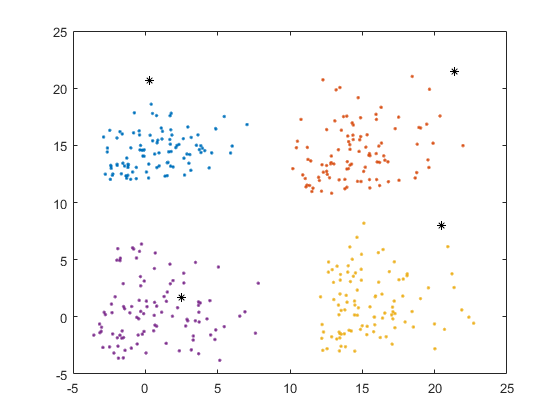

centers = [[rand*randi(10,1,1),     rand*randi(8,1,1)+20]  -randi(3,1,1);
           [rand*randi(10,1,1)+20,  rand*randi(12,1,1)+20] -randi(5,1,1);
           [rand*randi(10,1,1)+20,  rand*randi(12,1,1)]    -randi(3,1,1);
           [rand*randi(10,1,1),     rand*randi(12,1,1)]    -randi(4,1,1)];

figure(1); 
plot(data1(:,1), data1(:,2), '.', ...
    data2(:,1), data2(:,2), '.', ...
    data3(:,1), data3(:,2), '.', ...
    data4(:,1), data4(:,2), '.', ...
    centers(:,1), centers(:,2), '*k');

#### Inicia o loop de eventos

pertinence = linspace(0,0,length(data));
for i=1:1:epochMax
    cont = 1;
    for j=1:1:length(data)
        pertinence(j) = distance(data(j,:),centers);
        if(pertinence(j) == realClasses(j))
            cont = cont + 1;
        end
    end
    if cont >= length(realClasses)
        break;
    end
    centers = recalculateCenter(pertinence, data, centers);
end
fprintf("Total de interações: %d", i);

Total de interações: 3

#### Plota os resultados

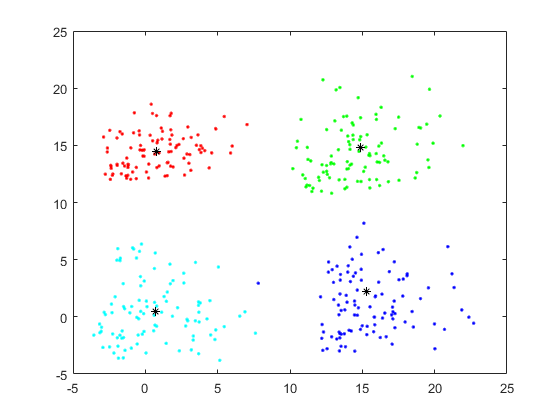

colors = ['r', 'g', 'b', 'c', 'm', 'y', 'w'];
figure(2);
plot(data(1,1), data(1,2), strcat('.',colors(pertinence(1)))); hold on
for i=2:1:length(data)
    plot(data(i,1), data(i,2), strcat('.',colors(pertinence(i))));
end
plot(centers(:,1), centers(:,2), '*k'); hold off;

#### Test com outra base de dados

define novos dados

data1 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(5,dataQtd,1)+15]-randi(3,dataQtd,1);
data2 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)+15]-randi(5,dataQtd,1);
data3 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(3,dataQtd,1);
data4 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(4,dataQtd,1);

data = [data1; data2; data3; data4];
realClasses = [linspace(1,1,length(data1)) linspace(2,2,length(data2)) linspace(3,3,length(data3)) linspace(4,4,length(data4))];

Passa os dados no modelo

cont = 0;
for j=1:1:length(data)
    pertinence(j) = distance(data(j,:),centers);
    if(pertinence(j) == realClasses(j))
        cont = cont + 1;
    end
end
fprintf("Acertos: %d | Erros: %d", cont, length(data)-cont);

Acertos: 394 | Erros: 6

Plota a classificação

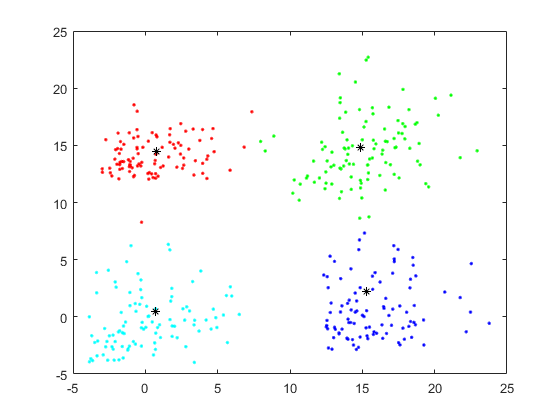

colors = ['r', 'g', 'b', 'c', 'm', 'y', 'w'];
figure(2);
plot(data(1,1), data(1,2), strcat('.',colors(pertinence(1)))); hold on
for i=2:1:length(data)
    plot(data(i,1), data(i,2), strcat('.',colors(pertinence(i))));
end
plot(centers(:,1), centers(:,2), '*k'); hold off;

#### Functions

realiza os calculos da distância do ponto até o centro pelo metodo euclidiano

function idx = distance(sample, centers)
    dist = linspace(0,0,length(centers));
    for i=1:1:length(centers)
        sm = 0;
        for j=1:1:length(sample)
            sm = sm + (sample(j)-centers(i,j))^2;
        end
        dist(i) = sqrt(sm);
    end
    [val idx] = min(dist);
end

recalcula a posição do centro

function res = recalculateCenter(pertinence, data, centers)
    [qtd, dimensity] = size(data);
    sumEle = zeros(length(centers),dimensity);
    sumQtd = linspace(0,0,length(centers));
    
    for i=1:1:qtd
        it = pertinence(i);
        for j=1:1:dimensity
            sumEle(it,j) = sumEle(it,j) + data(i,j);
        end 
        sumQtd(it) = sumQtd(it)+1;   
    end
    
    for i=1:1:length(centers)
        for j=1:1:dimensity
            if sumQtd(i) > 0
                centers(i,j) = sumEle(i,j)/sumQtd(i);
            end   
        end
    end
    res = centers;    
end
